# **Analysis Signal from INS**

clc
clear

Load signal

  Magnetic_field_bias:[1.6091872  -21.35169  -10.430104   41.79725]

opts = detectImportOptions('Magnetic_Field_Uncalibrated_2020-8-27_18-15-19.csv');
preview('Magnetic_Field_Uncalibrated_2020-8-27_18-15-19.csv',opts)

ans = 8×16 table
       t        uMx      uMy      uMz     xBias      yBias     zBias     heading       Var9         Var10         Var11         Var12         Var13         Var14         Var15         Var16   
    ________    ____    _____    _____    ______    _______    ______    _______    __________    __________    __________    __________    __________    __________    __________    __________

    5.67e+09      21    -14.4    -46.6    1.6092    

M = readmatrix('Magnetic_Field_Uncalibrated_2020-8-27_18-15-19.csv',opts);
MX = M(1:end,2);
MY = M(1:end,3);
MZ = M(1:end,4);
t = M(1:end,1);
t = t * 1e-9;
t = t - t(1);
for i = 2:length(t)
    if t(i-1) == t(i)
        t(i) = t(i) + 0.001;
    end
    if t(i) < t(i-1)
        t(i) = t(i-1) + 0.001; 
    end
end
MCal = MX - M(1,5);

Open signal Analyzer

signalAnalyzer

Gyro

opts = detectImportOptions('Gyroscope_Uncalibrated_2020-8-27_18-15-19.csv');
preview('Gyroscope_Uncalibrated_2020-8-27_18-15-19.csv',opts)

ans = 8×10 table
       Var1         Var2        Var3         Var4        Var5         Var6        Var7       Var8         Var9       ExtraVar1 
    __________    ________    _________    ________    _________    ________    ________    _______    __________    __________

    5.6704e+09    -0.40439     -0.28283    -0.77336    -0.013941    0.015234    0.018889    0.91227             0    {0×0 char}
    5.6803e+09    -0.32926     -0.37507      -0.978    -0.013941    0.015234    0.018889    0.91227    0.00012658    {0×0 char}
    5.6903e+09     -0.3207     -0.40745     -1.0855    -0.013941    0.015234    0.018889    0.91227    0.00025207    {0×0 char}
  

G = readmatrix('Gyroscope_Uncalibrated_2020-8-27_18-15-19.csv',opts);
GX = G(1:end,2);
GY = G(1:end,3);
GZ = G(1:end,4);
tG = G(1:end,1);
tG = tG * 1e-9;
tG = tG - tG(1);
for i = 2:length(tG)
    if tG(i-1) == tG(i)
        tG(i) = tG(i) + 0.001;
    end
    if tG(i) < tG(i-1)
        tG(i) = tG(i-1) + 0.001; 
    end
end
GCal = GX - G(1,5);

New Data

opts_2 = detectImportOptions('ground_noMov_noFilter.csv');
preview('ground_noMov_noFilter.csv',opts_2)

ans = 8×4 table
    Var1      Var2        Var3       Var4 
    _____    _______    ________    ______

    0.028    0.19034    -0.17238    9.8066
    0.049      0.164    -0.16281    9.8055
    0.069    0.18196     -0.1664     9.815
     0.09     0.1652    -0.16161     9.815
    0.111    0.16161    -0.16759    9.8055
    0.131     0.1652    -0.15802    9.8055
    0.153     0.1664    -0.16161    9.7995
    0.174    0.16999    -0.16879    9.8102


GNF = readmatrix('ground_noMov_noFilter.csv',opts_2);

opts_2 = detectImportOptions('ground_LPFandKF.csv');
preview('ground_LPFandKF.csv',opts_2)

ans = 8×4 table
    Timestamp        X             Y           Z    
    _________    __________    _________    ________

      0.008      -0.0077224    0.0030943    0.042285
      0.028      -0.0057332    0.0027982     0.04184
      0.049      -0.0051672    0.0031762    0.042071
      0.069      -0.0051044     0.001382    0.042102
      0.089      -0.0046819    0.0020334    0.042731
      0.111       -0.003508    0.0018543    0.042983
      0.133      -0.0034316    0.0025631    0.043002
      0.154      -0.0029014     0.002551    0.043154


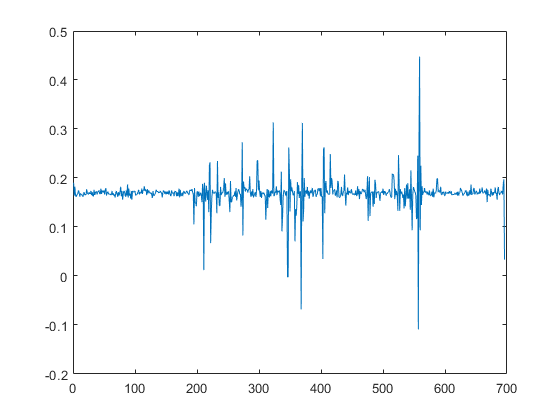

GLK = readmatrix('ground_LPFandKF.csv',opts_2);
t1 = 1:length(GNF(:,1));
t2 = 1:length(GLK(:,1));
plot(t1,GNF(:,2))

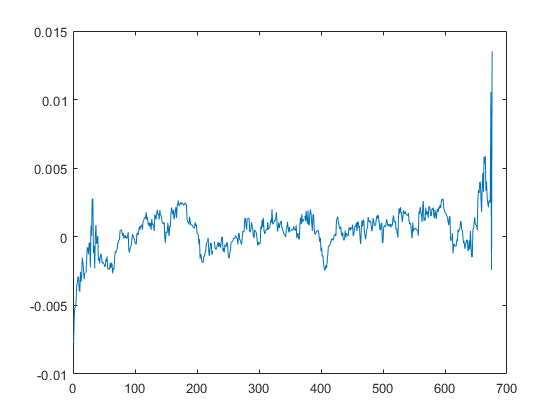

plot(t2,GLK(:,2))

A new Data

opts_2 = detectImportOptions('XY_Data_Set_2020-9-1_19-19-09.csv');
preview('XY_Data_Set_2020-9-1_19-19-09.csv',opts_2)

ans = 8×9 table
    stepNumber    strideLength    totalDistance      time      Heading    originalPointX    originalPointY    rotatedPointX    rotatedPointY
    __________    ____________    _____________    ________    _______    ______________    ______________    _____________    _____________

        0                 0                0       2.85e+09    0.83102             0                 0                 0                0   
        1           0.81357          0.81357       3.41e+09    0.94967       0.47346           0.66161          -0.66161          0.47346   
        2           0.81662           1.6302       3.91e+09    0.82936         1.025            1.2639           

xy_1 = readmatrix('XY_Data_Set_2020-9-1_19-19-09.csv',opts_2);
x_1 = xy_1(:,8);
y_1 = xy_1(:,9);
opts_2 = detectImportOptions('XY_Data_Set_2020-9-1_19-31-33.csv');
preview('XY_Data_Set_2020-9-1_19-31-33.csv',opts_2)

ans = 8×9 table
    stepNumber    strideLength    totalDistance      time      Heading    originalPointX    originalPointY    rotatedPointX    rotatedPointY
    __________    ____________    _____________    ________    _______    ______________    ______________    _____________    _____________

        0                 0                0       2.73e+09    -1.7452              0                 0                0                0   
        1           0.79102          0.79102       3.38e+09    -2.1849       -0.45582          -0.64648          0.64648         -0.45582   
        2            0.7832           1.5742       4.02e+09    -2.1245       -0.86769           -1.3126          

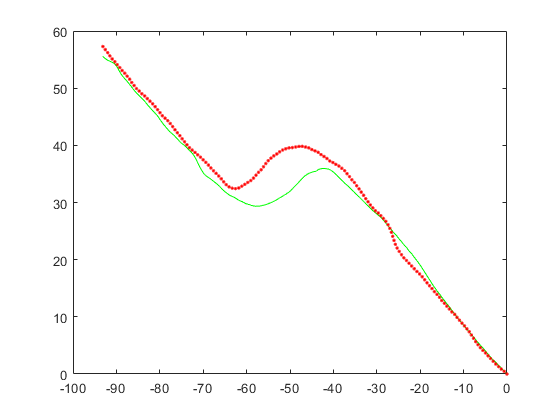

xy_2 = readmatrix('XY_Data_Set_2020-9-1_19-31-33.csv',opts_2);
x_2 = -1 .* xy_2(1:158,8);
y_2 = -1 .* xy_2(1:158,9);
t1 = 1:length(xy_1);
t2 = 1:length(xy_2);
plot(x_1,y_1,'g',x_2,y_2,'.r')

Angles

opts_2 = detectImportOptions('GyroscopeExplorer-2020-9-3-2-35-30.csv');
preview('GyroscopeExplorer-2020-9-3-2-35-30.csv',opts_2)

ans = 8×4 table
    Timestamp       X           Y            Z    
    _________    ________    ________    _________

      0.008      -0.81724    0.073708     -0.08553
      0.029      -0.72833     0.01752    -0.019178
      0.049      -0.72872    0.017911    -0.019479
       0.07      -0.72912    0.018319    -0.019809
       0.09      -0.72954    0.018755    -0.020128
      0.111      -0.72996      0.0192    -0.020461
      0.132      -0.73038    0.019637     -0.02078
      0.153      -0.73077    0.020023    -0.021077


GnF = readmatrix('GyroscopeExplorer-2020-9-3-2-35-30.csv',opts_2);
GnF = GnF(:,2) .* (180 / pi);
opts_2 = detectImportOptions('GyroscopeExplorer-2020-9-3-2-36-44.csv');
preview('GyroscopeExplorer-2020-9-3-2-36-44.csv',opts_2)

ans = 8×4 table
    Timestamp       X            Y            Z    
    _________    ________    _________    _________

      0.013        1.6717     0.071947     0.023524
      0.033      -0.75168    -0.014057     0.016965
      0.054      -0.74963    -0.014775     0.014535
      0.076      -0.74656    -0.012504    0.0081378
      0.097      -0.74726    -0.014649    0.0078751
      0.118      -0.74302    -0.017986    0.0078532
      0.141      -0.74872    -0.014095     0.012772
      0.169      -0.74872    -0.014095     0.012772


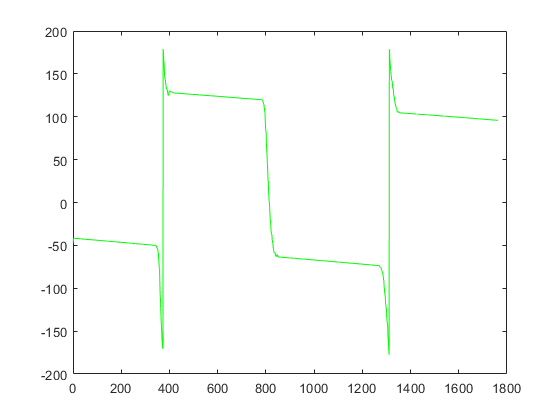

GF = readmatrix('GyroscopeExplorer-2020-9-3-2-36-44.csv',opts_2);
GF = GF(:,2) .* (180 / pi);
t1 = 1:length(GnF(:,1));
t2 = 1:length(GF(:,1));
plot(t1,GnF,'g')

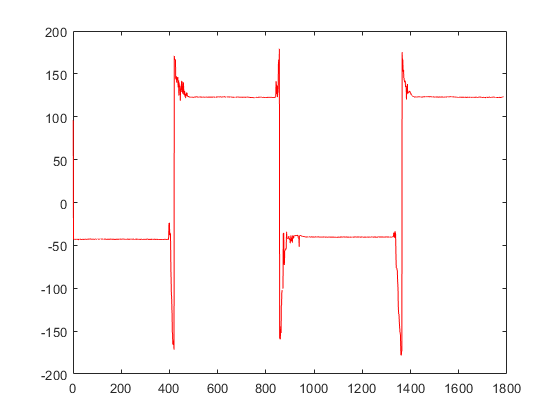

plot(t2,GF,'r')

Test 2

opts_2 = detectImportOptions('XY_Data_Set_2020-9-5_19-09-47.csv');
preview('XY_Data_Set_2020-9-5_19-09-47.csv',opts_2)

ans = 8×9 table
    stepNumber    strideLength    totalDistance      time      Heading     originalPointX    originalPointY    rotatedPointX    rotatedPointY
    __________    ____________    _____________    ________    ________    ______________    ______________    _____________    _____________

        0                 0                0       4.13e+09    -0.83402             0                  0                0                0   
        1           0.77686          0.77686       4.91e+09    -0.83833       0.51949           -0.57762          0.57762          0.51949   
        2           0.80922           1.5861       5.56e+09    -0.80023        1.0831            -1.1582     

xy_2 = readmatrix('XY_Data_Set_2020-9-5_19-09-47.csv',opts_2);
opts_2 = detectImportOptions('XY_Data_Set_2020-9-5_19-25-58.csv');
preview('XY_Data_Set_2020-9-5_19-25-58.csv',opts_2)

ans = 8×9 table
    stepNumber    strideLength    totalDistance      time      Heading    originalPointX    originalPointY    rotatedPointX    rotatedPointY
    __________    ____________    _____________    ________    _______    ______________    ______________    _____________    _____________

        0                 0               0         2.8e+09     -2.204              0                 0                0                0   
        1            0.7644          0.7644        3.63e+09    -2.0506       -0.35289          -0.67807          0.67807         -0.35289   
        2           0.76633          1.5307        4.25e+09    -2.0816       -0.72752           -1.3466          

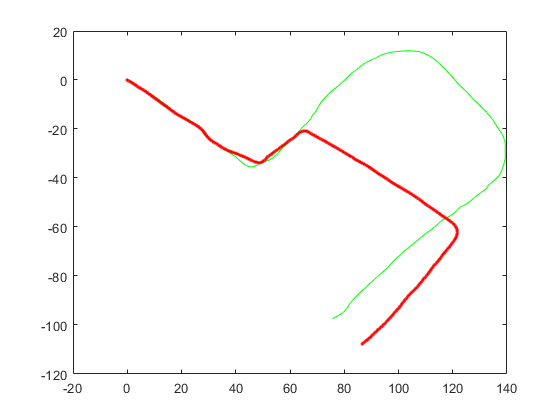

xy_1 = readmatrix('XY_Data_Set_2020-9-5_19-25-58.csv',opts_2);
x_1 = xy_1(:,8);
y_1 = xy_1(:,9);
x_2 = xy_2(:,8) + 86.66;
y_2 = xy_2(:,9) - 107.7;
t1 = 1:length(xy_1);
t2 = 1:length(xy_2);
plot(x_1,y_1,'g',x_2,y_2,'.r')